%% M1011 - Análisis de equilibrio estático: Grúa tipo pluma
% Cálculo de la fuerza del pistón y esfuerzo en el perno C
% ---------------------------------------------------------

clc; clear; close all;

%% --- Datos generales del sistema ---
W1 = 327.95;    % N (peso accesorio, si aplica)
W2 = 4905;      % N (peso principal de la carga)
L1 = 0.35;      % m
L2 = 0.86;      % m
L3 = 0.29;      % m
L4 = 0.97;      % m
L5 = 0.55;      % m
L6 = 2.00;      % m
L7 = 1.70;      % m

%% --- Datos del perno ---
r = 0.02;       % m (radio del perno)
h = 0.26;       % m (longitud efectiva de contacto)

%% --- Rango de ángulos de elevación (en grados) ---
theta = -15:1:80;

%% --- Cálculos geométricos intermedios ---
% Componentes de posición del pistón (proyecciones)
Bx = L3 .* cosd(theta) - L1;
By = L2 + L3 .* sind(theta);
hx = sqrt(Bx.^2 + By.^2);

% Ángulo relativo entre brazo y pistón
alpha = atand(By ./ Bx);

%% --- Cálculo de la fuerza del pistón (Fb) ---
% Ecuación de equilibrio de momentos (∑M = 0)
% Fb = [ W2 * ((L3 + L4)*cosθ) ] / [ (By/hx)*(L3*cosθ) - (Bx/hx)*(L3*sinθ) ]
Fb = (W2 .* ((L3 + L4) .* cosd(theta))) ./ ...
     (((By ./ hx) .* (L3 .* cosd(theta))) - ((Bx ./ hx) .* (L3 .* sind(theta))));

%% --- Cálculo del área del perno y esfuerzo ---
A = 2 * pi * r * (h + r);       % Área lateral de contacto [m²]
Y = (Fb / 2) / A;               % Esfuerzo promedio [N/m²] para θ=80° se toma el valor correspondiente

%% --- Resultados ---
fprintf('Área de contacto del perno A = %.4f m²\n', A);

Área de contacto del perno A = 0.0352 m²



% Tomamos el valor de Fb correspondiente a θ = 80° (último del vector)
Fb_80 = Fb(end);
Y_80 = (Fb_80 / 2) / A;
fprintf('Esfuerzo en el perno (θ = 80°): %.3e N/m²\n', Y_80);

Esfuerzo en el perno (θ = 80°): 1.260e+05 N/m²



% Mostrar tabla resumen
tabla = table(theta', alpha', Fb', 'VariableNames', {'Theta (°)', 'Alpha (°)', 'Fuerza_Piston (N)'});
disp(tabla);

    Theta (°)    Alpha (°)    Fuerza_Piston (N)
    _________    _________    _________________

       -15        -84.913           21919      
       -14        -85.035           21865      
       -13         -85.15           21815      
       -12        -85.258           21768      
       -11        -85.359           21724      
       -10        -85.452           21683      
        -9        -85.538           21644      
        -8        -85.617           21607      
        -7        -85.689           21571      
        -6        -85.755           21538      
        -5        -85.813           21506      
        -4        -85.865           21476      
        -3        -85.911           21446      
        -2         -85.95           21418      
        -1        -85.983           21390      
         0        -86.009           21363      
         1        -86.029        

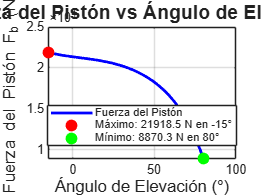


%% --- Gráfica Fuerza del Pistón vs Ángulo de Elevación ---
figure;
plot(theta, Fb, 'b-', 'LineWidth', 2);
grid on;
title('Fuerza del Pistón vs Ángulo de Elevación', 'FontSize', 14);
xlabel('Ángulo de Elevación (°)', 'FontSize', 12);
ylabel('Fuerza del Pistón F_b (N)', 'FontSize', 12);

% Identificar y marcar máximo y mínimo
[Fb_max, idx_max] = max(Fb);
[Fb_min, idx_min] = min(Fb);

hold on;
plot(theta(idx_max), Fb_max, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'red');
plot(theta(idx_min), Fb_min, 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'green');

legend('Fuerza del Pistón', ...
       sprintf('Máximo: %.1f N en %d°', Fb_max, theta(idx_max)), ...
       sprintf('Mínimo: %.1f N en %d°', Fb_min, theta(idx_min)), ...
       'Location', 'best');


fprintf('\nFuerza máxima: %.2f N en θ = %d°\n', Fb_max, theta(idx_max));


Fuerza máxima: 21918.53 N en θ = -15°


fprintf('Fuerza mínima: %.2f N en θ = %d°\n', Fb_min, theta(idx_min));

Fuerza mínima: 8870.29 N en θ = 80°
